usage: teamwork for week 14

author: 黄哲昊 毛晨光 鲁潇阳

date: 2020.6.6

clear all; close all; clc

**1. 复习非线性拟合. 阅读以下脚本**

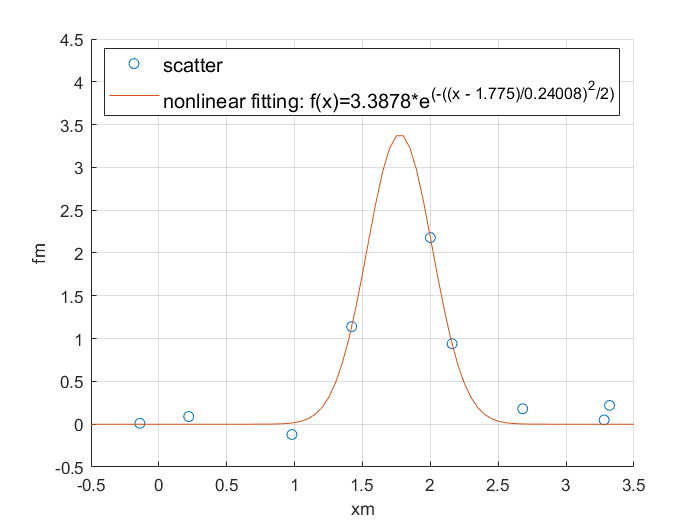

clear all; close all; clc
% 拟合的非线性数据
xm = [ -0.14; 0.22; 0.98; 1.42; 2.00; 2.16; 2.68; 3.28; 3.32 ];
fm = [ 0.01; 0.09; -0.12; 1.14; 2.18; 0.94; 0.18; 0.05; 0.22];

% 设定迭代的初始估计值
A = max(fm);                    % A等于fm中最大值
x0 = mean(xm);                  % x0等于xm的平均值
s = ( max(xm) - min(xm) ) /2;   % s等于xm中最大最小值的中间值

tol = 1e-6;                     % tol为误差上限
err = Inf;                      % err用于记录每次的误差
% 迭代过程
while err > tol
    
    f = A*exp(-((xm - x0)/s).^2/2); % 计算估计值
    d = fm - f;                     % 计算D

    z1 = f/A;                       % f关于A的偏导数
    z2 = f.*(xm - x0)/s^2;          % f关于x0的偏导数
    z3 = f.*(xm - x0).^2/s^3;       % f关于s的偏导数
    Z = [z1 z2 z3];
    
    da = (Z.'*Z)\(Z.'*d);           % 求解更新值
    A = A + da(1);                  % 更新A
    x0 = x0 + da(2);                % 更新x0
    s = s + da(3);                  % 更新s
    
    err = max(abs(da./[A; x0; s])); % 计算误差
end

% 作图显示最终迭代得到的函数
% 散点图观察数据分布情况
scatter(xm, fm)
hold on
grid on
func_1 = @(x) A.*exp(-((x - x0)./s).^2./2);
plot(-0.5:0.05:3.5, func_1(-0.5:0.05:3.5))
hold off
xlabel('xm')
ylabel('fm')
ylim([-0.5, 4.5])
title('nonlinear fitting by Newton-Gauss method')
string = ['nonlinear fitting: f(x)=', num2str(A), '*e^{(-((x - ', num2str(x0), ')/', num2str(s), ')^2/2)}'];
legend('scatter', string, 'Location', "best", 'FontSize', 12)

**    (1) 以上脚本计算了什么问题？请写出相应的理论函数和结果。**

解：上述脚本运用高斯-牛顿法求解非线性拟合的参数。

对于非线性的数据，给出$f=Ae^{-\frac12(\frac{x-x_0}{s})^2}$，其中$A,x_0,s$均为未知参数。

对每个参数$a_i^{(k+1)}=a_i^{k}+\Delta a_i$，令$\Delta A=\pmatrix{\Delta a_1 \cr \Delta a_2 \cr \vdots \cr \Delta a_m}$，并由$F^TF\Delta A=F^TD$得到，其中

$F_{n\times m}=\pmatrix{\frac{\partial f(x_1)}{\partial a_1} & \frac{\partial f(x_1)}{\partial a_2} & \dots & \frac{\partial f(x_1)}{\partial a_m} \cr
\frac{\partial f(x_2)}{\partial a_1} & \frac{\partial f(x_2)}{\partial a_2} & \dots & \frac{\partial f(x_2)}{\partial a_m} \cr
\vdots & \vdots && \vdots \cr
\frac{\partial f(x_n)}{\partial a_1} & \frac{\partial f(x_n)}{\partial a_2} & \dots & \frac{\partial f(x_n)}{\partial a_m} \cr}$，$D=\pmatrix{y_1 - f(x_1) \cr y_2-f(x_2) \cr \vdots \cr y_n - f(x_n)}$，重复迭代直到$max(\left| \frac{\Delta A}{A^{(k+1)}}\right|)<\epsilon$。

**    (2) 请在脚本的分段处添加注释， 以增加脚本的可读性。**

**    (3) 请添写代码以展示结果， 不要遗漏图形的标题， 坐标轴的标注， 理论函数的表达，以及参数值， 并且选择合适的坐标取值区间， 曲线宽度等。**

**2. 从Matlab读取数据**

clear all; close all; clc
load hospital.mat
hospital.Properties.VarNames(:)

ans = 7×1 cell 数组
    {'LastName'     }
    {'Sex'          }
    {'Age'          }
    {'Weight'       }
    {'Smoker'       }
    {'BloodPressure'}
    {'Trials'       }


**   若要获得有关体重的数据， 可以采用**

Sex = hospital.Sex;
Weight = hospital.Weight;
Weight_men = hospital.Weight(Sex=='Male');
Weight_women = hospital.Weight(Sex=='Female');

**   (1) 下面图形对男性和女性的体重做了正态分布的拟合。 请编写代码， 画出体重分布的直方图。**

**   (2) 请编写代码求得正态分布的相关参数。**

**   (3) 体重的分布与吸烟有关吗？ **

**   提示：请参考matlab内置函数`fitdist`, 或采用题1的方法进行拟合。**

解：

（1）（2）

h = histogram(Weight, 50, 'Normalization', 'probability');
%h_Wm = histogram(Weight_men, 25, 'Normalization', 'probability')
hold on
%h_Ww = histogram(Weight_women, 25, 'Normalization', 'probability')
%legend("Weight of men", "Weight of women", 'Location', 'best');
% 分别对男性体重、女性体重和全部体重进行正态分布
para_whole = fitdist(Weight, "Normal");
[pdca, gn, gl] = fitdist(Weight, 'Normal', 'By', Sex);
para_female = pdca{1};   %Distribution for females
para_male = pdca{2};     %Distribution for males
fprintf("对全部体重正态分布的参数为 mu=%f, sigma=%f", para_whole.mu, para_whole.sigma)

对全部体重正态分布的参数为 mu=154.000000, sigma=26.571421

fprintf("对女性体重正态分布的参数为 mu=%f, sigma=%f", para_female.mu, para_female.sigma)

对女性体重正态分布的参数为 mu=130.471698, sigma=8.303391

fprintf("对男性性体重正态分布的参数为 mu=%f, sigma=%f", para_male.mu, para_male.sigma)

对男性性体重正态分布的参数为 mu=180.531915, sigma=9.193218

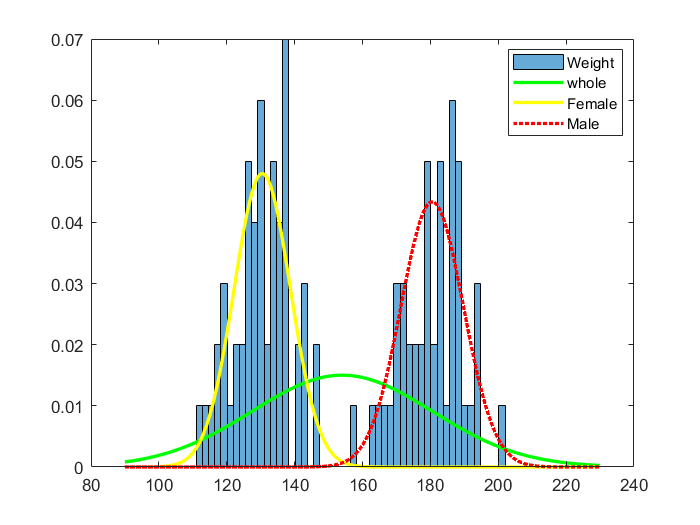

x_values = 90:1:230;
pdf_whole = pdf(para_whole, x_values);
pdf_female = pdf(para_female, x_values);
pdf_male = pdf(para_male, x_values);
plot(x_values, pdf_whole, 'LineWidth', 2, "Color", 'g')
plot(x_values, pdf_female, 'LineWidth', 2, "Color", 'y');
plot(x_values, pdf_male, 'Color', 'r', 'LineStyle', ':', 'LineWidth', 2);
legend("Weight", "whole", "Female", "Male", 'Location', "best")
hold off

（3）

Smoker = double(hospital.Smoker);
R = corrcoef(Weight, Smoker);
fprintf("体重分布与吸烟的相关系数为：%f", R(1, 2));

体重分布与吸烟的相关系数为：0.215586

从相关系数可以看出体重分布与吸烟相关性不大。

**3.  随机行走是匈牙利的数学家Polya在1921年最早提出的。 请模拟一维粒子的随机行走. 每次走一步， 每步向左和向右的概率均为1/2. 另外在原点**$$x=0$$**处设置反弹墙，行走至原点后必然改变方向走下一步。在**$$x=n$$**处设置吸收墙， 行走至此粒子将被吸收，行走结束。**

**   请计算从原点**$$x=0$$**开始, 平均多少步数后粒子会被吸收？**

解：

clear all; close all; clc
% 分别对n=[3, 5, 7, 10]进行模拟,每次模拟次数为1000
n = [3, 5, 7, 10];
avgtimes = zeros(1, 4);
for i=1:length(n)
    sum = 0;
    for step=1:1000
        sum = sum + count_walk(n(i));
    end
    avgtimes(i) = sum / 1000;
end
fprintf("x=n\t%d\t%d\t%d\t%d \navg\t%.2f\t%.2f\t%.2f\t%.2f", ...
    n(1), n(2), n(3), n(4), ...
    avgtimes(1), avgtimes(2), avgtimes(3), avgtimes(4))

x=n	3	5	7	10 
avg	9.06	25.26	48.44	99.33

通过模拟可以发现，平均都是经过$n^2$步后粒子被吸收，与解析解相符。

**4. 用舍取法计算积分**


$$    $$
    I=\int_0^1 dx_1 \int_0^1 dx_2 \cdots\int_0^1 dx_{10}\left(x_1+x_2+\cdots+x_{10}\right) ^2
    $$$$


**    (1)**$ $N=10,100,1000,10000,100000$$**. 分别取**$$\max(25,\sqrt{N})$$**次计算结果, 每次计算的随机数列的种子不同。**

**    (2) 理论值是155/6. 计算均方差, 绘制均方差**$$\sigma(N)$$**和**$$N$$**的双对数图，验证**$$\sigma(N)\propto N^{-1/2}$$

解：

（1）（2）

clear all; close all; clc
% N = 10^1, 10^2, 10^3, 10^4, 10^5
N_4 = 5;
mean_4 = zeros(1, 5);    %prelocate mean
std_4 = zeros(1, 5);     %prelocate std
for i = 1:N_4
    n = ceil(max(25, sqrt(10^i)));
    my = zeros(1, n);
    for k = 1:n
        rng('shuffle'); % different seed
        x = rand(10, 10^i);
        y = rand(1, 10^i)*100;
        x = sum(x, 1).*sum(x, 1);
        my(k) = 100 * sum(y <= x) / 10^i;
    end
    mean_4(i) = mean(my);
    std_4(i) = std(my);
end
fprintf("N\t%.1e\t%.1e\t%.1e\t%.1e\t%.1e " + ...
    "\navg\t%.2f\t%.2f\t%.2f\t%.2f\t%.2f" + ...
    "\nstd\t%.2f\t%.2f\t%.2f\t%.2f\t%.2f", ...
    1e1, 1e2, 1e3, 1e4, 1e5, ...
    mean_4(1), mean_4(2), mean_4(3), mean_4(4), mean_4(5), ...
    std_4(1), std_4(2), std_4(3), std_4(4), std_4(5));

N	1.0e+01	1.0e+02	1.0e+03	1.0e+04	1.0e+05 
avg	23.20	25.00	25.61	25.80	25.84
std	14.35	4.30	1.49	0.37	0.14

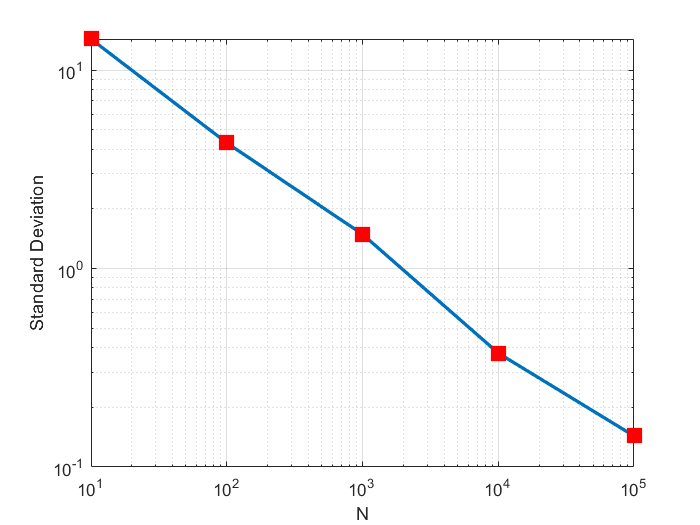

%绘制均方差与N的双对数图
loglog(10.^[1:5], std_4, '-s', 'MarkerSize',10,...
    'MarkerEdgeColor','red','MarkerFaceColor','red','LineWidth',2 )
xlabel('N'),ylabel('Standard Deviation')
grid on

从图中可得大约N每提升两个数量级，均方差下降一个数量级，即$$\sigma(N)\propto N^{-1/2}$$

**5. 用平均值法计算积分，并估计其误差**

**   (1)  **$$I=\displaystyle\int_0^1 \sqrt{x+\sqrt{x}}dx$     $

**   (2) **$ $I=\displaystyle\int_0^{5/4}\int_0^{5/4}\sqrt{4-x^2-y^2}dxdy$ $

**   (3) **$$I=\displaystyle\int\limits_0^{7/10}\int\limits_{0}^{4/5}\int\limits_0^{9/10}\int\limits_0^1\int\limits_0^{11/10}\sqrt{6-x^2-y^2-z^2-u^2-w^2}dxdydzdydw$$

解：

（1）

clear all; close all; clc
f_5_1 = @(x) sqrt(x + sqrt(x));
n = 10000; % 试验次数
my_5_1 = zeros(1, ceil(sqrt(n)));
for k=1:ceil(sqrt(n))
    rng('shuffle'); % different seed
    x = rand(1, n);
    f = f_5_1(x);
    my_5_1 = mean(f);
end
I_5_1 = mean(my_5_1);
I_5_1_check = integral(f_5_1, 0, 1);
E_5_1 = abs(I_5_1 - I_5_1_check)/I_5_1_check;
fprintf("5.1用平均值计算的积分值为：%f,准确值为：%f,两者的相对误差为：%f",I_5_1, I_5_1_check, E_5_1);

5.1用平均值计算的积分值为：1.044124,准确值为：1.045301,两者的相对误差为：0.001127

（2）

f_5_2 = @(x, y) sqrt(4 - x.^2 - y.^2);
n = 10000; % 试验次数
my_5_2 = zeros(1, ceil(sqrt(n)));
for k=1:ceil(sqrt(n))
    rng('shuffle'); % different seed
    x = 5/4*rand(1, n);
    y = 5/4*rand(1, n);
    f = f_5_2(x, y);
    my_5_2 = (5/4)^2*mean(f);
end
I_5_2 = mean(my_5_2);
I_5_2_check = integral2(f_5_2, 0, 5/4, 0, 5/4);
E_5_2 = abs(I_5_2 - I_5_2_check)/I_5_2_check;
fprintf("5.2用平均值计算的积分值为：%f,准确值为：%f,两者的相对误差为：%f",I_5_2, I_5_2_check, E_5_2);

5.2用平均值计算的积分值为：2.669106,准确值为：2.669054,两者的相对误差为：0.000020

（3）

clear all; close all; clc
f_5_3 = @(x, y, z, u, w) sqrt(6-x.^2-y.^2-z.^2-u.^2-w.^2);
n = 10000; % 试验次数
my_5_3 = zeros(1, ceil(sqrt(n)));
for k=1:ceil(sqrt(n))
    rng('shuffle'); % different seed
    x = 7/10*rand(1, n);
    y = 4/5*rand(1, n);
    z = 9/10*rand(1, n);
    u = rand(1, n);
    w = 11/10*rand(1, n);
    f = f_5_3(x, y, z, u, w);
    my_5_3 = 7/10*4/5*9/10*11/10*mean(f);
end
I_5_3 = mean(my_5_3)

I_5_3 = 1.1893


%求解五重积分的准确值
%syms x y z u w
%func_5_3 = sqrt(6-x.^2-y.^2-z.^2-u.^2-w.^2);
%I_5_3_check = vpaintegral(vpaintegral(vpaintegral(vpaintegral(vpaintegral(func_5_3, x, [0 7/10]), y, [0 4/5]), z, [0 9/10]), u, [0 1]), w, [0 11/10]);
%E_5_3 = abs(I_5_3 - I_5_3_check)/I_5_3_check;
%fprintf("5.2用平均值计算的积分值为：%f,准确值为：%f,两者的相对误差为：%f",I_5_3, I_5_3_check, E_5_3);

**6. 设辅助函数**$$w(x)=e^{-ax}$$**， 采用重要抽样法计算**


$$    $$
    \int _0^{\pi} \frac{dx}{x^2+\cos ^2{x}}
    $$$$


**    选择合适的**$$a$$**，使得计算结果的均方差最小**

解：

由于$y=\int^x_0{e^{-ax'}dx'}=\frac1a-\frac1ae^{-ax}$，求得反函数为$x=-\frac1aln(1-ay)$

clear all; close all; clc
func_6 = @(x) 1./(x.^2 + (cos(x)).^2);
I_6_check =  integral(func_6, 0, pi)

I_6_check = 1.5812

[my_mean_6, my_std_6] = important_sampling(0.1)

my_mean_6 = 1.5798

my_std_6 = 0.0092

验证重要抽样法计算结果正确。

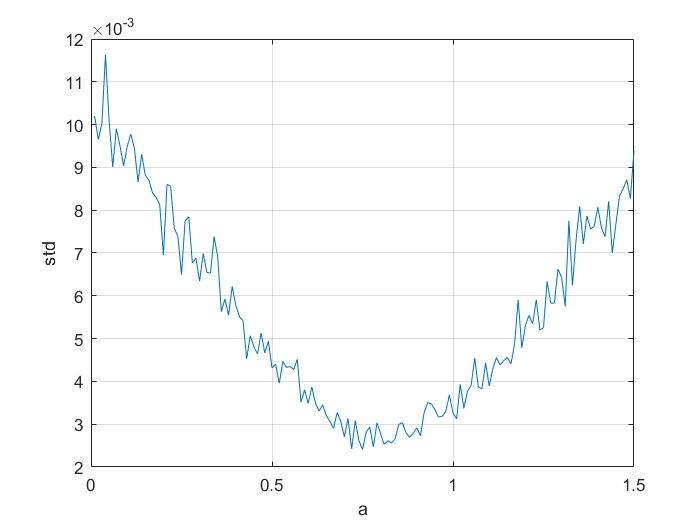

a_6 = 0:0.01:1.5;
std_6 = zeros(1, length(a_6));
for i=1:length(a_6)
    [my_mean, my_std] = important_sampling(a_6(i));
    std_6(i) = my_std;
end
plot(a_6, std_6)
xlabel('a')
ylabel('std')
grid on

minposition=find(std_6==min(std_6));
fprintf("当a为：%f，计算结果的均方差最小", a_6(minposition))

当a为：0.750000，计算结果的均方差最小

a_check = 0.9493

当$a \in [0.7, 0.9]$的范围内时，均方差最小。

*********************************************functions************************************************

rand_walk：随机行走

返回向左走-1，向右走+1

function w = rand_walk()
    r = rand();
    if r < 0.5
        w = -1;
    else
        w = 1;
    end
end

count_walk：模拟随机行走

根据输入值n，记录在多少步数后粒子会被吸收

function c = count_walk(n)
    % 假设第一步向右走;此后回到0时，也向右走下一步
    cur_pos = 1;
    c = 1;
    while cur_pos ~= n
        cur_pos = cur_pos + rand_walk();
        c = c+1;
        if cur_pos == 0
            cur_pos = 1;
            c = c+1;
        end
    end
    
end

important_sampling(N)：重要抽样法求积分

根据x的范围$[0, \pi]$，则y的范围为$[0, \int_0^\pi e^{-ax}dx]$，则积分$\int^\pi_0 f(x)dx=\int_0^{(1-e^{-a\pi})/a}\frac{f(x(y))}{w(x(y))}dy \approx\frac{(1-e^{-a\pi})}{a}\frac1N \sum^N_{k=1}\frac{f(x_k)}{w(x_k)}$

function [my_mean, my_std] = important_sampling(a)
    n = 10000; % 试验次数
    my = zeros(1, ceil(sqrt(n)));
    for k=1:ceil(sqrt(n))
        rng('shuffle'); % different seed
        Y = rand(1, n)*(1-exp(-a.*pi))/a;
        X = -1./a.*log(1-a*Y);
        W = exp(-a.*X);
        func = @(x) 1./(x.^2 + (cos(x)).^2);
        FF = func(X)./W.*integral(@(x) exp(-a.*x), 0, pi); % 要乘以辅助函数在区间上的积分
        my(k) = mean(FF);
    end
    my_mean = mean(my);
    my_std = std(my);
end